# Servomecanismos                      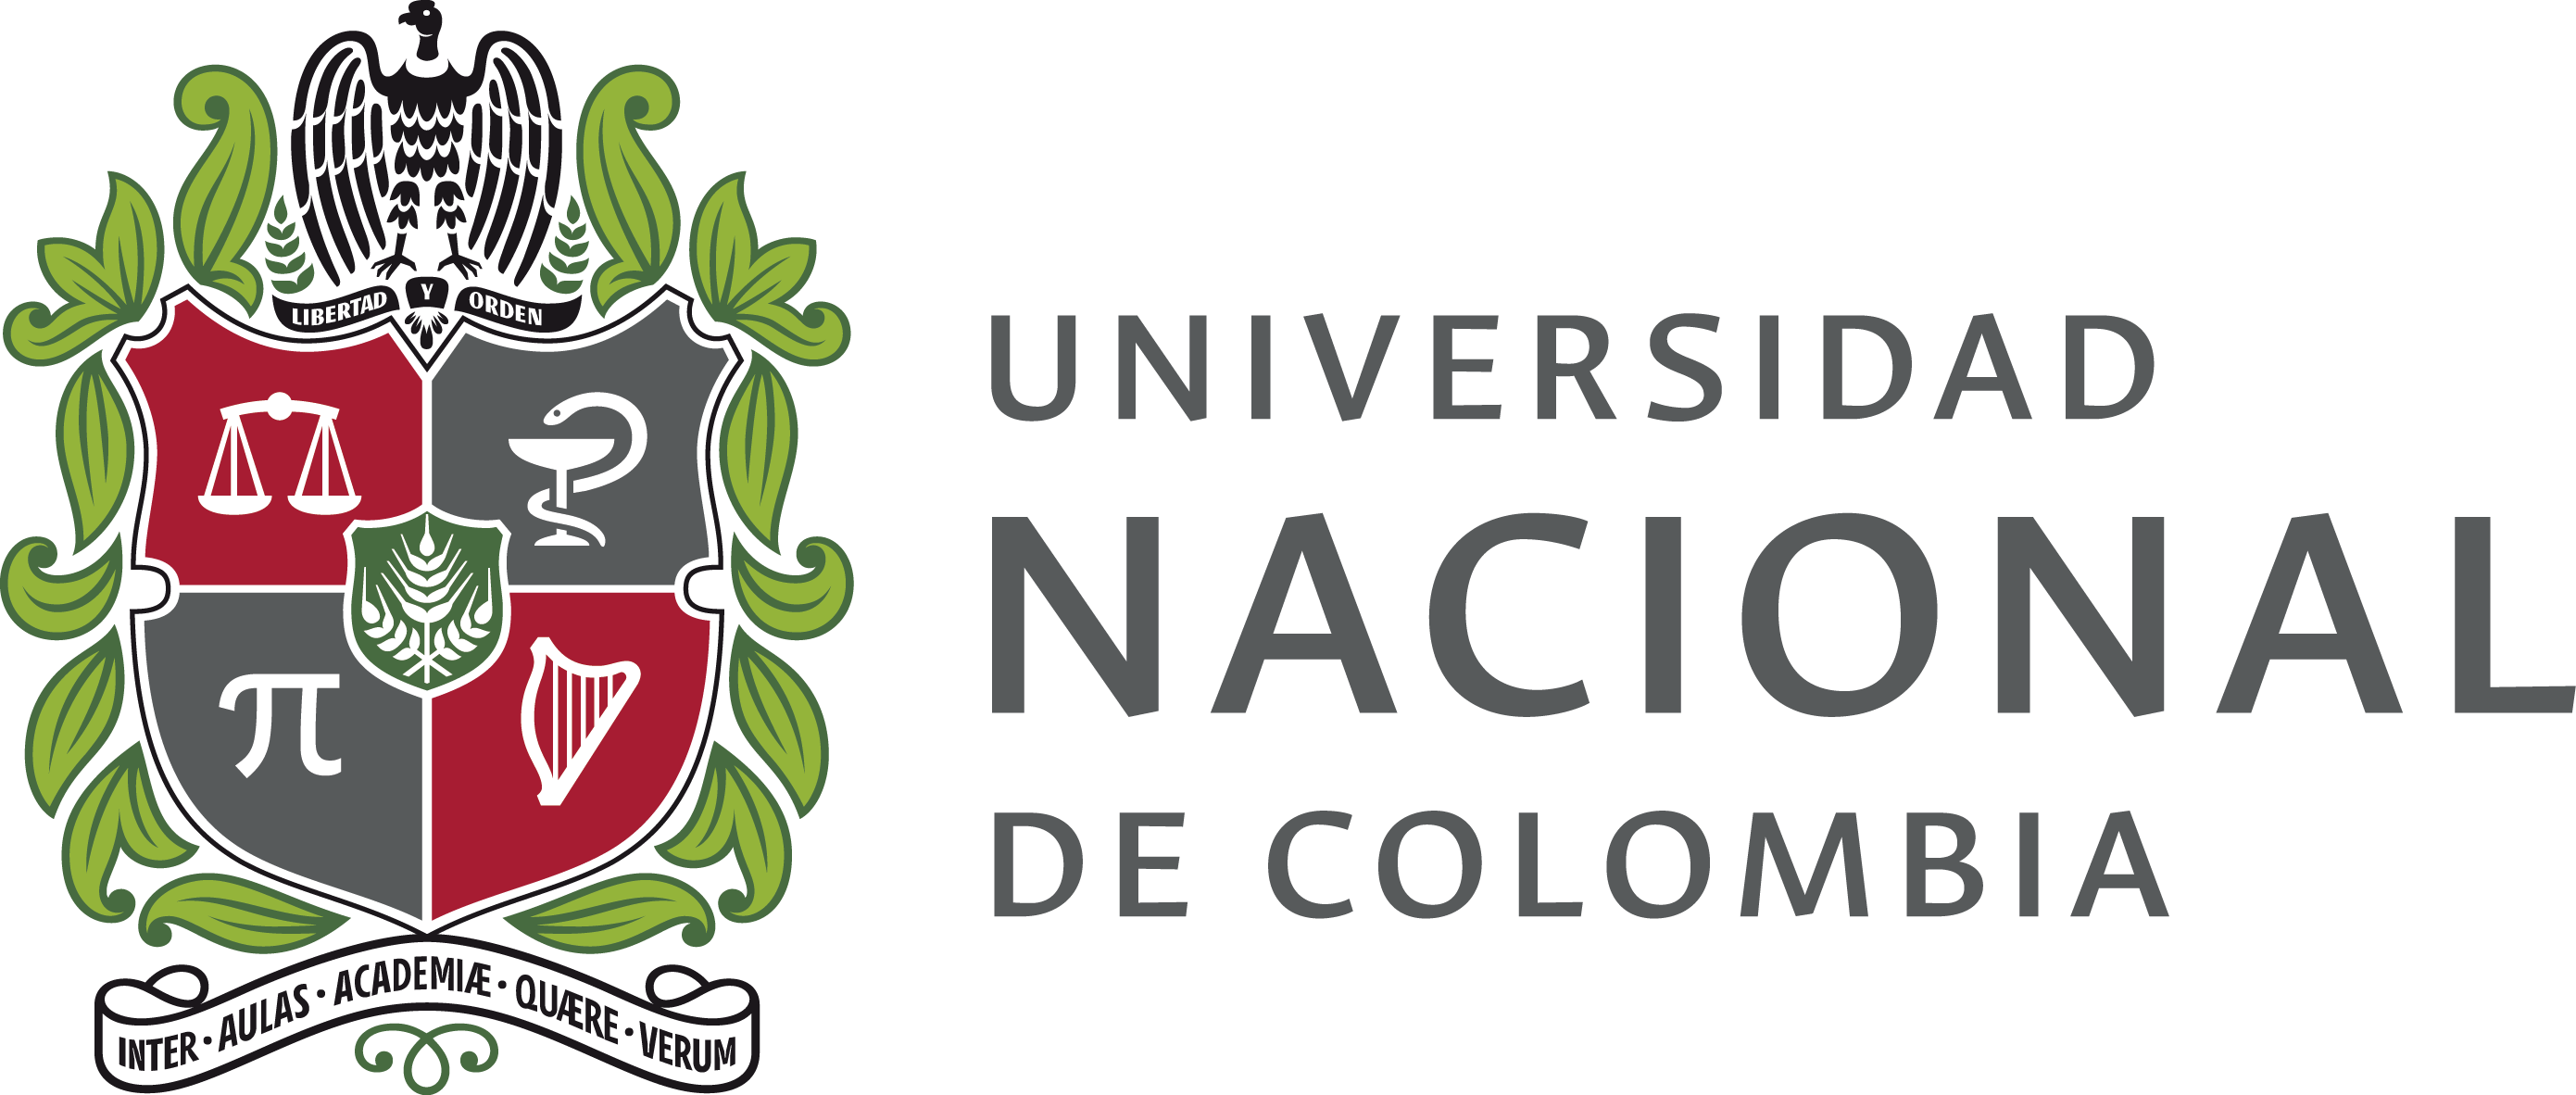

# Proyecto Industrial - Diseño de Perfiles

`Samuel David Sanchez Cardenas.  Ingeniería Mecatrónica. 2025 - S1.`

`____________________________________________________`

## Desarrollo

Diseño de perfiles

%% PERFIL TRAPEZOIDAL (Guía Box Forming / Motion Control Project)
% - Perfil trapezoidal simétrico: t = t1 + t2 + t3, con t1=t3
% - Entradas: L (recorrido), T (tiempo total), a (aceleración)
% - Salidas: x(t), v(t), a(t), y parámetros (Vmax, t1, t2, etc.)
%
% Demo: Rutina tipo CASE ERECTOR (Y, RotX, RotZ) por etapas:
% 1b: Y + RotZ, 1c: Y + RotX, Home: retorno simultáneo

clear; close all; clc

%% ---------------------- PARÁMETROS GLOBALES (AJUSTA AQUÍ) ----------------------
% Producción (la guía menciona 5–10 cajas/min como rango de diseño)
cajas_por_min = 8;      % [cajas/min]  (elige entre 5 y 10 para probar)
tu = 60 / cajas_por_min; % [s/caja]

% Reparto temporal (según supuestos típicos de la guía)
t_formado = tu/2;       % [s] avance
t_home    = tu/2;       % [s] retorno
tb = t_formado/2;       % [s] etapa 1b
tc = t_formado/2;       % [s] etapa 1c

% Geometría (demo guía: L1=L2=1.5 m; rotaciones de 90°)
L1 = 1.5;               % [m]
L2 = 1.5;               % [m]
rot90 = 90;             % [deg]

% Aceleraciones elegidas (ajústalas; el código verifica factibilidad)
aY = 6.0;               % [m/s^2]
aX = 400;               % [deg/s^2]
aZ = 400;               % [deg/s^2]

% Resolución temporal para discretización y gráficas
dt = 1e-3;              % [s] (si va lento, sube a 2e-3 o 5e-3)

%% ---------------------- PERFIL POR ETAPAS (ABSOLUTO EN POSICIÓN) ----------------------
% Eje Y (m): 1b: 0->L1, 1c: L1->L1+L2, Home: L1+L2->0
Y_1b   = trapProfile(+L1,        tb,    aY, 0,      dt, "Eje Y (1b)");
Y_1c   = trapProfile(+L2,        tc,    aY, L1,     dt, "Eje Y (1c)");
Y_home = trapProfile(-(L1+L2),   t_home,aY, L1+L2,  dt, "Eje Y (Home)");

% Eje RotZ (deg): 1b: 0->90, 1c: hold 90, Home: 90->0
Z_1b   = trapProfile(+rot90,     tb,    aZ, 0,      dt, "RotZ (1b)");
Z_1c   = holdProfile( rot90,     tc,          dt, "RotZ (hold 1c)");
Z_home = trapProfile(-rot90,     t_home,aZ, rot90,  dt, "RotZ (Home)");

% Eje RotX (deg): 1b: hold 0, 1c: 0->90, Home: 90->0
X_1b   = holdProfile( 0,         tb,          dt, "RotX (hold 1b)");
X_1c   = trapProfile(+rot90,     tc,    aX, 0,      dt, "RotX (1c)");
X_home = trapProfile(-rot90,     t_home,aX, rot90,  dt, "RotX (Home)");

% Concatenar en un solo ciclo (tu)
Y = stitchProfiles({Y_1b, Y_1c, Y_home});
X = stitchProfiles({X_1b, X_1c, X_home});
Z = stitchProfiles({Z_1b, Z_1c, Z_home});

% Marcadores de cambio de etapa
tB = tb;
tC = tb + tc;
tEnd = tu;

%% ---------------------- RESUMEN DE PARÁMETROS (tipo MAM) ----------------------
fprintf("\n=== RESUMEN (útil para parametrizar bloques tipo MAM: Distance/Velocity/Accel) ===\n");


=== RESUMEN (útil para parametrizar bloques tipo MAM: Distance/Velocity/Accel) ===


printMoveSummary(Y_1b);   printMoveSummary(Z_1b);

- Eje Y (1b)     | dL=   1.500 | T= 1.875 | a=   6.000 (a_min=   1.707) | Vmax=   0.867 | t1= 0.144 t2= 1.586
- RotZ (1b)      | dL=  90.000 | T= 1.875 | a= 400.000 (a_min= 102.400) | Vmax=  51.542 | t1= 0.129 t2= 1.617


printMoveSummary(Y_1c);   printMoveSummary(X_1c);

- Eje Y (1c)     | dL=   1.500 | T= 1.875 | a=   6.000 (a_min=   1.707) | Vmax=   0.867 | t1= 0.144 t2= 1.586
- RotX (1c)      | dL=  90.000 | T= 1.875 | a= 400.000 (a_min= 102.400) | Vmax=  51.542 | t1= 0.129 t2= 1.617


printMoveSummary(Y_home); printMoveSummary(X_home); printMoveSummary(Z_home);

- Eje Y (Home)   | dL=  -3.000 | T= 3.750 | a=   6.000 (a_min=   0.853) | Vmax=  -0.831 | t1= 0.138 t2= 3.473
- RotX (Home)    | dL= -90.000 | T= 3.750 | a= 400.000 (a_min=  25.600) | Vmax= -24.397 | t1= 0.061 t2= 3.628
- RotZ (Home)    | dL= -90.000 | T= 3.750 | a= 400.000 (a_min=  25.600) | Vmax= -24.397 | t1= 0.061 t2= 3.628


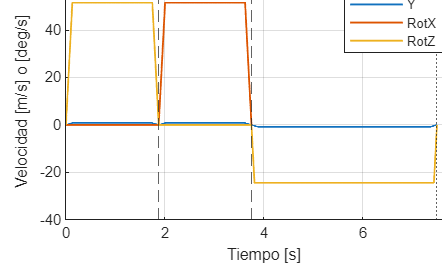


%% ---------------------- GRÁFICAS ----------------------
% 1) Velocidades (secuenciación Y+Z, luego Y+X, luego Home simultáneo)
figure("Name","Velocidades - ciclo completo");
plot(Y.t, Y.v, "LineWidth", 1.2); hold on
plot(X.t, X.v, "LineWidth", 1.2);
plot(Z.t, Z.v, "LineWidth", 1.2);
xline(tB, "--"); xline(tC, "--"); xline(tEnd, ":");
grid on; xlabel("Tiempo [s]"); ylabel("Velocidad [m/s] o [deg/s]");
legend("Y","RotX","RotZ","Location","best");
title("Velocidades (perfil trapezoidal por etapas)");

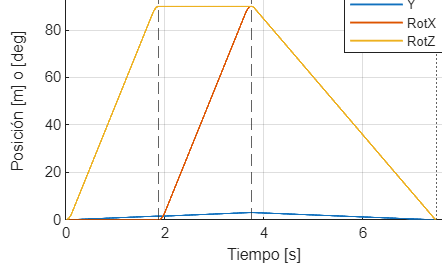


% 2) Posiciones
figure("Name","Posiciones - ciclo completo");
plot(Y.t, Y.x, "LineWidth", 1.2); hold on
plot(X.t, X.x, "LineWidth", 1.2);
plot(Z.t, Z.x, "LineWidth", 1.2);
xline(tB, "--"); xline(tC, "--"); xline(tEnd, ":");
grid on; xlabel("Tiempo [s]"); ylabel("Posición [m] o [deg]");
legend("Y","RotX","RotZ","Location","best");
title("Posiciones (absolutas) por eje");

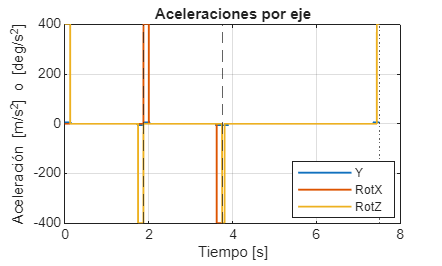


% 3) Aceleraciones
figure("Name","Aceleraciones - ciclo completo");
plot(Y.t, Y.acc, "LineWidth", 1.2); hold on
plot(X.t, X.acc, "LineWidth", 1.2);
plot(Z.t, Z.acc, "LineWidth", 1.2);
xline(tB, "--"); xline(tC, "--"); xline(tEnd, ":");
grid on; xlabel("Tiempo [s]"); ylabel("Aceleración [m/s^2] o [deg/s^2]");
legend("Y","RotX","RotZ","Location","best");
title("Aceleraciones por eje");

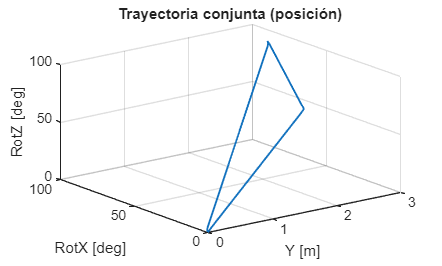


% 4) Espacio articular (trayectoria Y vs RotX vs RotZ)
figure("Name","Trayectoria en espacio articular");
plot3(Y.x, X.x, Z.x, "LineWidth", 1.2);
grid on; xlabel("Y [m]"); ylabel("RotX [deg]"); zlabel("RotZ [deg]");
title("Trayectoria conjunta (posición)");


%% ====================== FUNCIONES LOCALES ======================

function prof = trapProfile(dL, T, a, x0, dt, name)
% Perfil trapezoidal simétrico (v(0)=v(T)=0). Devuelve posición absoluta.
% dL: desplazamiento (puede ser negativo)
% T : tiempo total
% a : aceleración (magnitud, >0)
% x0: posición inicial absoluta
% dt: paso
    arguments
        dL (1,1) double {mustBeFinite}
        T  (1,1) double {mustBePositive}
        a  (1,1) double {mustBePositive}
        x0 (1,1) double {mustBeFinite}
        dt (1,1) double {mustBePositive}
        name (1,1) string = "move"
    end

    L = abs(dL);
    sgn = sign(dL); if sgn == 0, sgn = 1; end

    % Condición de factibilidad (discriminante >= 0): si a es muy baja, no hay solución
    disc = (a*T)^2 - 4*a*L;
    if disc < -1e-12
        a_min = 4*L/(T^2);
        error("Movimiento '%s' NO factible: a=%.4g < a_min=%.4g (L=%.4g, T=%.4g).", ...
            name, a, a_min, L, T);
    end
    disc = max(disc, 0);

    % Dos soluciones para Vmax; se toma Vmax1 (la menor) para estabilizar antes (t1 menor)
    Vmax = (a*T - sqrt(disc))/2;

    t1 = Vmax/a;
    t2 = T - 2*t1;
    if t2 < 0, t2 = 0; end % por redondeo numérico (caso triangular: t2=0)

    x1 = 0.5*a*t1^2;
    x2 = Vmax*t2;

    t = 0:dt:T;
    v = zeros(size(t));
    acc = zeros(size(t));
    x = zeros(size(t));

    % Regiones
    i1 = (t <= t1);
    i2 = (t > t1) & (t <= (t1+t2));
    i3 = (t > (t1+t2));

    % 1) Aceleración
    acc(i1) = +a;
    v(i1)   = a*t(i1);
    x(i1)   = 0.5*a*(t(i1)).^2;

    % 2) Crucero
    acc(i2) = 0;
    v(i2)   = Vmax;
    x(i2)   = x1 + Vmax*(t(i2)-t1);

    % 3) Deceleración
    tau = t(i3) - (t1+t2);
    acc(i3) = -a;
    v(i3)   = Vmax - a*tau;
    x(i3)   = x1 + x2 + Vmax*tau - 0.5*a*(tau).^2;

    % Ajuste de signo y posición absoluta
    prof.t = t(:);
    prof.x = (x0 + sgn*x(:));
    prof.v = (sgn*v(:));
    prof.acc = (sgn*acc(:));

    prof.name = name;
    prof.dL = dL;
    prof.T = T;
    prof.a = a;
    prof.Vmax = Vmax*sgn;   % con signo
    prof.t1 = t1; prof.t2 = t2; prof.t3 = t1;
    prof.a_min = 4*L/(T^2);
end

function prof = holdProfile(x_hold, T, dt, name)
% Segmento en reposo (posición constante)
    t = 0:dt:T;
    prof.t = t(:);
    prof.x = x_hold*ones(numel(t),1);
    prof.v = zeros(numel(t),1);
    prof.acc = zeros(numel(t),1);

    prof.name = name;
    prof.dL = 0;
    prof.T = T;
    prof.a = 0;
    prof.Vmax = 0;
    prof.t1 = 0; prof.t2 = T; prof.t3 = 0;
    prof.a_min = 0;
end

function full = stitchProfiles(profs)
% Concatena perfiles (evitando duplicar el primer punto de cada segmento)
    t_all = [];
    x_all = [];
    v_all = [];
    a_all = [];

    t_offset = 0;
    for k = 1:numel(profs)
        p = profs{k};
        if k == 1
            idx = 1:numel(p.t);
        else
            idx = 2:numel(p.t); % evita duplicar el punto de unión
        end
        t_all = [t_all; p.t(idx) + t_offset];
        x_all = [x_all; p.x(idx)];
        v_all = [v_all; p.v(idx)];
        a_all = [a_all; p.acc(idx)];
        t_offset = t_all(end);
    end

    full.t = t_all;
    full.x = x_all;
    full.v = v_all;
    full.acc = a_all;
end

function printMoveSummary(p)
% Resumen corto para llevar a MAM: Distance, Velocity, Accel (y chequeo a_min)
    fprintf("- %-14s | dL=%8.3f | T=%6.3f | a=%8.3f (a_min=%8.3f) | Vmax=%8.3f | t1=%6.3f t2=%6.3f\n", ...
        p.name, p.dL, p.T, p.a, p.a_min, p.Vmax, p.t1, p.t2);
end
